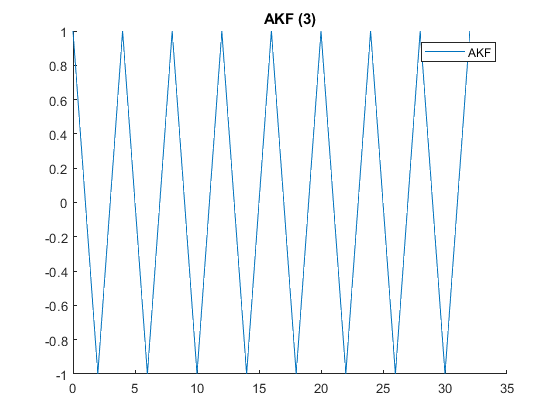

clear;
%{
******************** 
******** a *********
********************
%}

SEQ_LENGTH = 32;
OVERSAMPLING = 4;
J = 6;
user = 3;

walshCodes = hadamard(SEQ_LENGTH);
oversampledCodes = zeros(size(walshCodes)*2^OVERSAMPLING);
for i=1:length(walshCodes)
    oversampledCodes(i,:) = oversampl(walshCodes(i,:), OVERSAMPLING); 
end

oversampledUserSig = oversampledCodes(user,:);
periodicAkf = kkf_per(oversampledUserSig, oversampledUserSig).';

axes = linspace(0, 32, length(periodicAkf)); 
%Plotten der AKF und KKF
figure;
hold on;
plot(axes, periodicAkf / 512);
legend('AKF');
title(sprintf('AKF (%i)', user));
hold off;

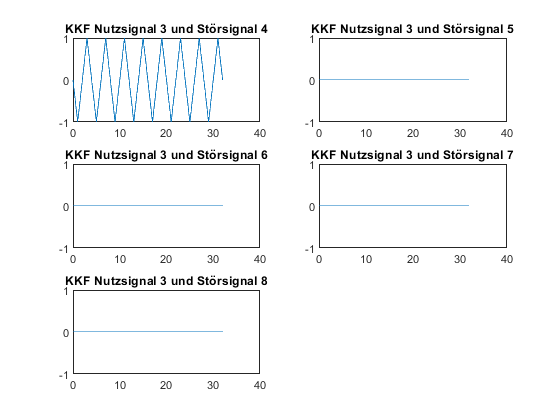

walshCodesSize = size(oversampledCodes);
clutterPeriodicKkf = zeros(J - 1, walshCodesSize(2) + 1);
figure;
%6 Signale, 5 Störsignale
for i = 4:8
    subplot(3,2, i-user);
    newSig = kkf_per(oversampledUserSig, oversampledCodes(i,:)).';
    clutterPeriodicKkf(i-user, :) = newSig;
    plot(axes, clutterPeriodicKkf(i-user, :) / 512);
    title(sprintf('KKF Nutzsignal %i und Störsignal %i', user, i));
end

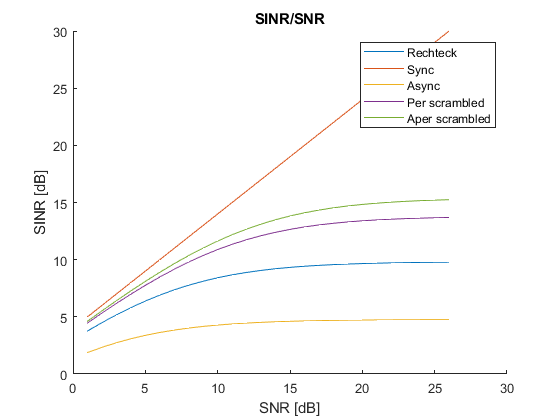

%{
******************** 
******** b *********
********************
%}
Gp = SEQ_LENGTH;
S = 1;

dbSNR = 5:30; 
SNR = 10.^(dbSNR./10);
N = S./SNR;

rectSINR = Gp./((J-1)*(2/3)+(Gp./SNR));
dbRectSINR= 10*log10(rectSINR);

figure;
hold on;
plot(dbRectSINR);

% periodisch
I = sum(mean(clutterPeriodicKkf(:, 1) / 512.^2));
dbSINR = sinr(1, I);

plot(dbSINR);

%{
******************** 
******** c *********
********************
%}
scrambledWalshCodes = zeros(J, length(walshCodes));
scrambledClutterPerKkf = zeros(J - 1, length(oversampledUserSig) + 1);
scrambledClutterAperKkf = zeros(J - 1, length(oversampledUserSig) * 2 - 1);

mSeq = get_m_sequences(511, 1);

userScrambleCode = mSeq(1, 1:32);
scrambledWalshCodes(1,:) = walshCodes(user,:).*(userScrambleCode./userScrambleCode);
oversampledUserScrambleCode = oversampl(scrambledWalshCodes(1,:), OVERSAMPLING);

scrambledUserSigPer = kkf_per(oversampledUserSig, oversampledUserScrambleCode).';
scrambledUserSigAper = kkf_aper(oversampledUserSig,oversampledUserScrambleCode).';

for i=2:J
    scrambleCode = mSeq(1+32*(i-1):32*(i));
    scrambledWalshCodes(i,:) = walshCodes(2+i,:).*(scrambleCode./userScrambleCode);
    
    oversampledScramble = oversampl(scrambledWalshCodes(i,:), OVERSAMPLING);
    scrambledSigPer = kkf_per(oversampledUserSig, oversampledScramble).';
    scrambledSigAper = kkf_aper(oversampledUserSig, oversampledScramble).';
    
    scrambledClutterPerKkf(i-1,:) = scrambledSigPer;
    scrambledClutterAperKkf(i-1,:) = scrambledSigAper;
end

clutterPerI = 0;
scrambledClutterPerI = 0;
scrambledClutterAperI = 0;

for i=1:J-1
    clutterPerI = clutterPerI + sum(mean((clutterPeriodicKkf(i,:) / 512).^2));
    scrambledClutterPerI = scrambledClutterPerI + sum(mean((scrambledClutterPerKkf(i,:) / 512).^2));
    scrambledClutterAperI = scrambledClutterAperI + sum(mean((scrambledClutterAperKkf(i,:) / 512).^2));
end

%{
******************** 
******** d *********
********************
%}

plot(sinr(1, clutterPerI));
plot(sinr(1, scrambledClutterPerI));
plot(sinr(1, scrambledClutterAperI));

xlabel('SNR [dB]');
ylabel('SINR [dB]');
title('SINR/SNR');
legend('Rechteck', 'Sync','Async','Per scrambled','Aper scrambled')
hold off;

function dbSINR = sinr(S, I)
    dbSNR = 5:30;
    SNR = 10.^(dbSNR./10);
    N = S./SNR;
    
    SINR = S./(N + I);
    dbSINR = 10*log10(SINR);
end